# Arrow Flow Model

This model is able to plot the expected velocity and pressure distributions around an arrow of variable shape through the use of a dynamic Fourier conformal mapping of the flow about the circulating cylinder to the actual geometry of the arrow. By varying the geometry, it is possible to see how the flow about the arrow changes.

% Creates the domain of analysis
max_domain_x = 10;
max_domain_y = 10;
num_axial_pos = 100;

xpos = linspace(-max_domain_x, max_domain_x, num_axial_pos);
ypos = linspace(-max_domain_x, max_domain_x, num_axial_pos);

[xx, yy] = meshgrid(xpos, ypos);
zz = xx + 1j*yy;

% Adds useful anonymous functions
prof_plot = @(x, f) plot(real(x), imag(x), f); % Profile plot

## Geometric Model

The geometric model of the fin is produced by means of external functions. Sample functions have been created and can be found in the Geometry folder and can readily be used. Additional function can be easily used but it will be necessary to be careful so as to ensure that the Kutta condition has been met. *Further consideration require the even spacing of points via the provided interpolation function to ensure that the conformal transformation is not biased or otherwise skewed and can be reliably used as a conformal transformation.*

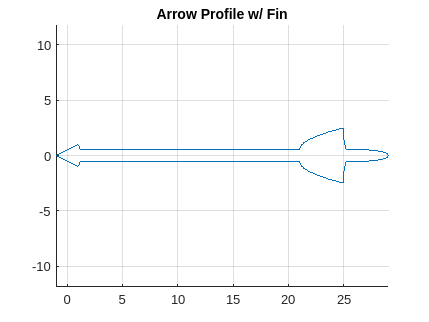

% Allows setting of arrow geometry
L_c = 2; % Forward cap length
D = 1; % Diameter of body
h_c = 0.5; % Forward cap height

L_m = 20; % Main body length
L_f = 4; % Total fin length
L_t = 2; % Trailing body length
L_tc = 2; % End cap length

L_fl = 4; % Length of leading fin section
h_f = 1; % Height of fin


curve_res = 2000; % Used for producing high density ge
% ometry

interp_num_points_1 = 750; % Number of evenly distanced points
interp_num_points_2 = 500;

% Generates the arrow with given parameters (and runs through the
% interpolation algorithms to space the sampled points out). Note that
% once the interpolation algorithm is done and the points are distributed
% correctly, especially at the middle of the profile, the final end point
% will be removed to not duplicate the starting point

% fin_profile_z = create_linear_ellipse_fin_profile(L_f, L_fl, h_f, curve_res);
% fin_profile_z = create_linear_french_curve_fin_profile(L_f, L_fl, h_f, curve_res);
% fin_profile_z = create_linear_old_english_kl_fin_profile(L_f, L_fl, h_f, curve_res);
% fin_profile_z = create_linear_old_english_sl_fin_profile(L_f, L_fl, h_f, curve_res);
% fin_profile_z = create_linear_pope_young_curve_fin_profile(L_f, L_fl, h_f, curve_res);
fin_profile_z = create_linear_shield_fin_profile(L_f, L_fl, h_f, curve_res);

tip_profile_cap = create_rounded_tip_profile(L_c, h_c, D, curve_res);
tip_profile_pointy = create_pointy_tip_profile(L_c, h_c, D, curve_res);


tip_profile = tip_profile_pointy;

arrow_profile_with_fin_z = create_arrow_profile_with_fin(D, L_c, L_tc, L_m, L_f, L_t, fin_profile_z, tip_profile, curve_res);
interp_arrow_profile_with_fin_z = interp_even_dists_from_z_profile(arrow_profile_with_fin_z, interp_num_points_1+1); % Adds additional point
interp_arrow_profile_with_fin_z = interp_arrow_profile_with_fin_z(1:(end-1)); % Removes end point

arrow_profile_without_fin_z = create_arrow_profile_without_fin(D, L_c, L_tc, L_m, L_f, L_t, tip_profile, curve_res);
interp_arrow_profile_without_fin_z = interp_even_dists_from_z_profile(arrow_profile_without_fin_z, interp_num_points_1+1); % Adds additional point
interp_arrow_profile_without_fin_z = interp_arrow_profile_without_fin_z(1:(end-1)); % Removes end point

% Plots the profiles
figure
grid on
hold on
% daspect([1 1 1])
axis equal
prof_plot(interp_arrow_profile_with_fin_z(1:end), '');
title('Arrow Profile w/ Fin')

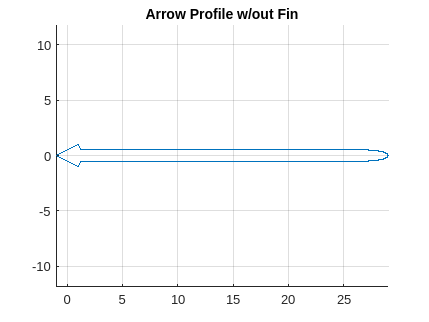


figure
grid on
hold on
axis equal
prof_plot(arrow_profile_without_fin_z, '');
title('Arrow Profile w/out Fin')

### Fourier Series

Use of a Fourier series allows for generation of a function that can be used as a coordinate mapping from a simple disk (with known radius about the origin) to that of the fin profile.

disk_angs = linspace(0, 2*pi, interp_num_points_1);
disk_z = exp(1j*disk_angs);

num_fourier_terms = 40;

ratio_interp_w_fin = interp_arrow_profile_with_fin_z ./ disk_z;
[c0_w_fin, cn_w_fin, n_cn_w_fin] = calc_coeffs_cfourier_series(ratio_interp_w_fin, disk_angs, 2*pi, num_fourier_terms);
ratio_interp_w_fin_fourier = calc_vals_from_cfourier_series(c0_w_fin, cn_w_fin, n_cn_w_fin, 2*pi, disk_angs);

disp('plots of fourier-fitted ratios for fin case')

plots of fourier-fitted ratios for fin case


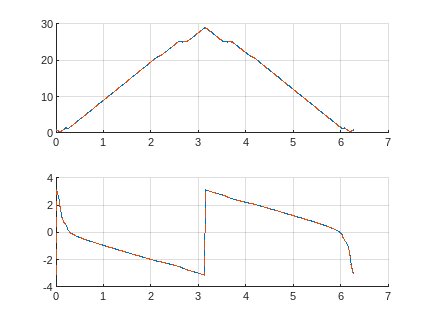


figure
tiledlayout(2, 1)
nexttile
grid on
hold on
plot(disk_angs, abs(ratio_interp_w_fin));
plot(disk_angs, abs(ratio_interp_w_fin_fourier), '--');
nexttile
grid on
hold on
plot(disk_angs, angle(ratio_interp_w_fin));
plot(disk_angs, angle(ratio_interp_w_fin_fourier), '--');

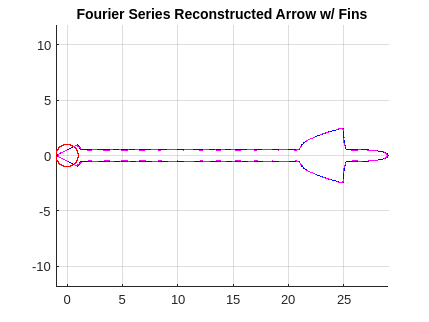


figure
grid on
hold on
axis equal
prof_plot(disk_z, 'r')
prof_plot(interp_arrow_profile_with_fin_z, 'b');
prof_plot(disk_z .* ratio_interp_w_fin_fourier, 'm--')
title('Fourier Series Reconstructed Arrow w/ Fins')


ratio_interp_wout_fin = interp_arrow_profile_without_fin_z ./ disk_z;
[c0_wout_fin, cn_wout_fin, n_cn_wout_fin] = calc_coeffs_cfourier_series(ratio_interp_wout_fin, disk_angs, 2*pi, num_fourier_terms);
ratio_interp_wout_fin_fourier = calc_vals_from_cfourier_series(c0_wout_fin, cn_wout_fin, n_cn_wout_fin, 2*pi, disk_angs);

disp('plots of fourier-fitted ratios for non-fin case')

plots of fourier-fitted ratios for non-fin case


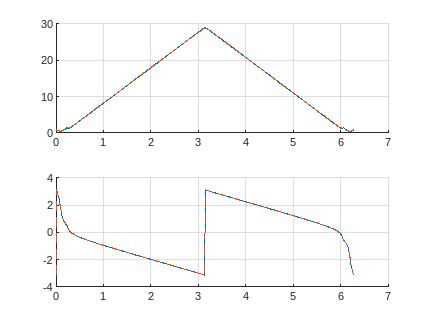


figure
tiledlayout(2, 1)
nexttile
grid on
hold on
plot(disk_angs, abs(ratio_interp_wout_fin));
plot(disk_angs, abs(ratio_interp_wout_fin_fourier), '--');
nexttile
grid on
hold on
plot(disk_angs, angle(ratio_interp_wout_fin));
plot(disk_angs, angle(ratio_interp_wout_fin_fourier), '--');

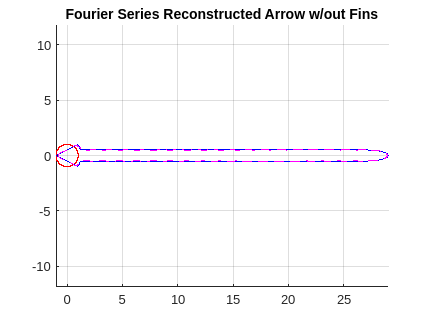


figure
grid on
hold on 
axis equal
prof_plot(disk_z, 'r')
prof_plot(interp_arrow_profile_without_fin_z, 'b')
prof_plot(disk_z .* ratio_interp_wout_fin_fourier, 'm--')
title('Fourier Series Reconstructed Arrow w/out Fins')

At this point, the geometry and the associated function necessary for calculating the conformal map have been identified and shown to be correct within appropriate error margins for the original function.

## Complex Flow

### Flow Around Circulating Cylinder

At this point the geometry and the associated functions necessary for calculating the final geometry are known. The complex flow, however, must first be generated before the mapping can occur.

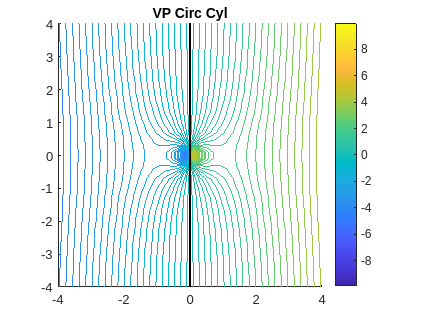

fs_vel = 1;
fs_ang = 0; % 1/4*pi/2;
circ_rad = 1;
doublet_str = fs_vel*(circ_rad)^(2);

% derived with the new equation (rotation applied to doublet)
sp_ang = 0; %-1/4*pi/2;
vortex_str = -2*circ_rad*fs_vel*sin(fs_ang - sp_ang);

% derived with the old equation
% sp_ang = 0;
% vortex_str = -circ_rad*exp(1j*sp_ang)*(fs_vel*exp(-1j*fs_ang) - doublet_str/circ_rad^2*exp(-1j*2*sp_ang))*1j;

w_circ_cyl = cflow_circ_cyl(fs_vel, fs_ang, doublet_str, vortex_str, zz);
[vp_circ_cyl, sf_circ_cyl] = flow_fields_from_cflow(w_circ_cyl);

circ_cyl_lim = 4;

figure
hold on
axis equal
contour(xpos, ypos, vp_circ_cyl, 100);
contour(xpos, ypos, vp_circ_cyl, [-0.005 0.005], 'k')
title('VP Circ Cyl')
xlim([-circ_cyl_lim circ_cyl_lim])
ylim([-circ_cyl_lim circ_cyl_lim])
colorbar

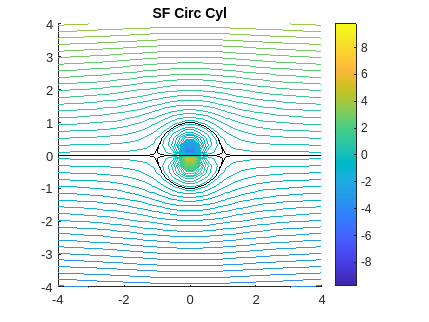


figure
hold on
axis equal
contour(xpos, ypos, sf_circ_cyl, 100);
contour(xpos, ypos, sf_circ_cyl, [-0.005 +0.005], 'k') % Plots the body streamline (value of 0)
title('SF Circ Cyl')
xlim([-circ_cyl_lim circ_cyl_lim])
ylim([-circ_cyl_lim circ_cyl_lim])
colorbar

Now that the flow around the circulating cylinder has been added, this flow must be remapped to new coordinates as given by the result of the previously identified conformal mapping.

### Conformal Mapping

It should be noted that the conformal mapping is changing the the position (from the z-plane to the zeta-plane) of the corresponding w-plane values. Fundamentally it is just a geometrical operation on this relation. However, this does change the derivative terms which affects the flow velocit6y, etc.

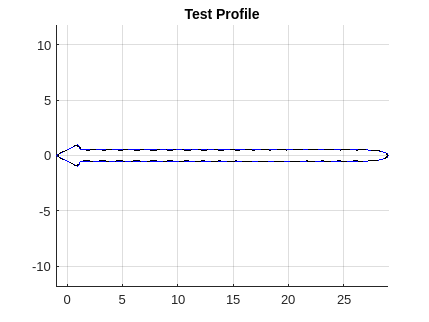

% Need to evaluate stable limit of the conformal mapping. There is a small
% region around the actual Fourier transform in which it is stable but not
% much elsewhere

r_stable = 1;
% Based on observations, with 25 terms of Fourier coefficients,
% qualitatively, it appears that the maximum r_stable that should be used
% is 1.07. The ringing effects of the Fourier series becomes very
% pronounced after this point.

wout_fins_min_stable_z = (disk_z) .* fourier_conf_map_transf(c0_wout_fin, cn_wout_fin, n_cn_wout_fin, r_stable * disk_z, 2*pi, 1.0);

figure
hold on
grid on
axis equal
prof_plot(interp_arrow_profile_without_fin_z, 'b')
prof_plot(disk_z .* ratio_interp_wout_fin_fourier, 'm--')
prof_plot(wout_fins_min_stable_z, 'k--');
title('Test Profile')

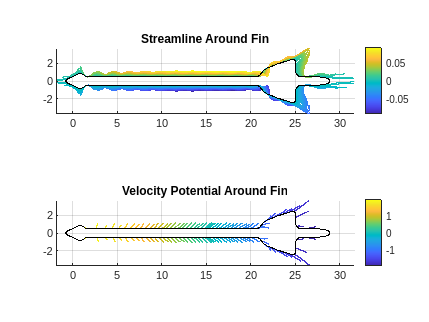


% Unable to apply the conformal map to only a band of radii which is
% required, therefore need to change strategy of domain discretization
% rpos = linspace(0.9, 1.0, interp_num_points_2);
rpos = linspace(1.0, 1.05, interp_num_points_2);
angpos = linspace(0, 2*pi, interp_num_points_1);

[rr, angang] = meshgrid(rpos, angpos);
zz_radial = rr .* exp(1j*angang);

% Given that we have expressed the mapping as a ratio of the position on
% the actual geometry over the equivalent point on the disk, we need to
% create an equivalent array that can multiply by the corresponding disk
% position for every value in the map.

w_zz_radial = cflow_circ_cyl(fs_vel, fs_ang, doublet_str, vortex_str, zz_radial);
zeta_disk_ratio = fourier_conf_map_transf(c0_w_fin, cn_w_fin, n_cn_w_fin, zz_radial, 2*pi, 1.00);
zeta = transpose(disk_z) * ones(1, size(zeta_disk_ratio, 2)) .* zeta_disk_ratio; % Creates multiple rows the angle vectors

figure
tiledlayout(2, 1)
nexttile
hold on
grid on
axis equal
% prof_plot(zeta, '')
contour(real(zeta), imag(zeta), imag(w_zz_radial), 50);
contour(real(zeta), imag(zeta), imag(w_zz_radial), [-0.001 0.001])
prof_plot(zeta(:, 1), 'k')
colorbar
title('Streamline Around Fin')

nexttile
hold on
grid on
axis equal
contour(real(zeta), imag(zeta), real(w_zz_radial), 50);
contour(real(zeta), imag(zeta), real(w_zz_radial), [-0.001 0.001])
prof_plot(zeta(:, 1), 'k')
colorbar
title('Velocity Potential Around Fin')

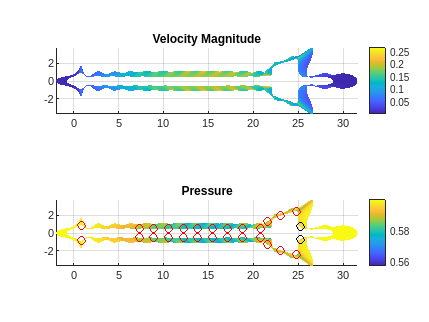


% Ensures that the numerical derivative is taken in radial direction to
% prevent massive velocity chnage seen due to crossover from +ve to -ve
% imaginary component when crossing over 180 degree location

% NOTE: having problems with the complex derivative, will give up on this
% method of approach and will compute derivatie using the derivative of the
% streamine itself

% dw_dzeta_radial = transpose((calc_cflow_deriv(w_zz_radial', zeta')));
dw_dzeta_radial = calc_cflow_deriv(w_zz_radial, zeta);
[u_zeta_radial, v_zeta_radial, V_zeta_radial] = flow_vels_from_cflow_deriv(dw_dzeta_radial, 1); % Flips the velocity directions

% [u_zz_radial, v_zz_radial, V_zz_radial] = flow_vels_from_vel_pot(imag(w_zz_radial), zz_radial);


figure
tiledlayout(2, 1)
nexttile
hold on
grid on
axis equal
contourf(real(zeta), imag(zeta), V_zeta_radial, 100, 'LineColor', 'none');
colorbar
title('Velocity Magnitude')

p_zeta_radial = calc_pressure_no_grav_bern(1.2, V_zeta_radial, fs_vel, 0);

% Finds the local minimum pressure points (which will be used to assess the
% expected location of boundary layer separation) and therefore determine
% the approximate constant minimum pressure to use over the region of the
% arrow affected by the wake.

surf_zeta = zeta(:, 1);
p_surf_zeta = p_zeta_radial(:, 1);

min_p_idxs = islocalmin(p_surf_zeta);
% Finds the minimum pressure points (not guaranteed to be the points of
% separation but we can manimpulate these to find them)
surf_zeta_min_p = surf_zeta(min_p_idxs);
p_surf_min_p = p_surf_zeta(min_p_idxs);

% Finds the minimum pressure points corresponding to separation that occurs
% at the top of the boundary layer. Indices are provided with respect to
% the currently identified minimum points.
[~, sep_points_idx_from_min] = sort(real(surf_zeta_min_p), 'descend'); % Rightmost points

% Grabs the 2 first points provided they are the rightmost minimum pressure
% points and thus correspond to the point of boundary layer separation
surf_zeta_sep = surf_zeta_min_p(sep_points_idx_from_min(1:2));
p_surf_sep = p_surf_min_p(sep_points_idx_from_min(1:2));


nexttile
hold on
grid on
axis equal
contourf(real(zeta), imag(zeta), p_zeta_radial, 100, 'LineColor', 'none');
scatter(real(surf_zeta_min_p), imag(surf_zeta_min_p), 'r');
scatter(real(surf_zeta_sep), imag(surf_zeta_sep), 'k')
colorbar
title('Pressure')

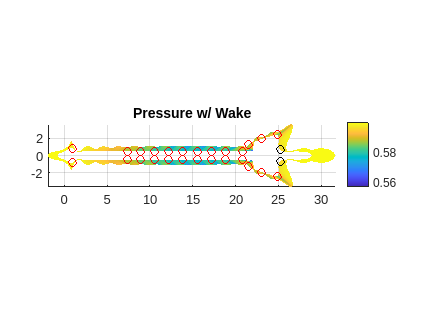


% For visualization purposes, will compute both the updated pressure and
% velocity graphs to present the new boundary layer separation profile and
% the additional profile contributing to pressure drag.

bottom_sep_point = surf_zeta_sep(1);
bottom_sep_pressure = p_surf_sep(1);

top_sep_point = surf_zeta_sep(2);
top_sep_pressure = p_surf_sep(2);

% Additionally assumes that the boundary layer follows the same profile
% direction as that of the uniform flow
sep_slope = tan(fs_ang);
top_sep_yint = imag(top_sep_point) - sep_slope * real(top_sep_point);
bottom_sep_yint = imag(bottom_sep_point) - sep_slope * real(bottom_sep_point);

top_sep_bound = @(x) sep_slope * x + top_sep_yint;
bottom_sep_bound = @(x) sep_slope * x + bottom_sep_yint;

p_zeta_radial_w_wake = p_zeta_radial; % Changes the pressure in the wake region

for j=1:size(zeta, 1)
    for i=1:size(zeta, 2)
        curr_z_pos = zeta(j, i);

        curr_x = real(curr_z_pos);
        curr_y = imag(curr_z_pos);
        
        if curr_x > real(top_sep_point) || curr_x > real(bottom_sep_point)
            % The point is to the right of at least one stagnation point
            % and therefore is likely to be within the wake, need to check
            % this further though

            if curr_y < top_sep_bound(curr_x) && curr_y > bottom_sep_bound(curr_x)
                
                % Calculated the interpolated minimum pressure to make sure
                % a discontinuity isn't introduced when generating the
                % expected minimum pressures in the wake region.

                curr_offset_z = curr_z_pos - bottom_sep_point;
                sep_diff_z = top_sep_point - bottom_sep_point;

                curr_offset_vec = [real(curr_offset_z) ; imag(curr_offset_z)];
                sep_diff_vec = [real(sep_diff_z) ; imag(sep_diff_z)];

                interp_min_p = dot(curr_offset_vec, sep_diff_vec) / norm(sep_diff_vec) * (top_sep_pressure - bottom_sep_pressure) + bottom_sep_pressure;
                
                % Computes the pressure difference between the separation
                % pressures and the expected potential flow pressures
                
                % p_diff = interp_min_p - p_zeta_radial(j,i);
                % p_zeta_radial_w_wake(j,i) = p_diff;

                % Uses the interpolated minimum pressure
                p_zeta_radial_w_wake(j, i) = interp_min_p;
            end
        end
    end
end

figure
hold on
grid on
axis equal
contourf(real(zeta), imag(zeta), p_zeta_radial_w_wake, 100, 'LineColor', 'none');
scatter(real(surf_zeta_min_p), imag(surf_zeta_min_p), 'r');
scatter(real(surf_zeta_sep), imag(surf_zeta_sep), 'k')
colorbar
title('Pressure w/ Wake')

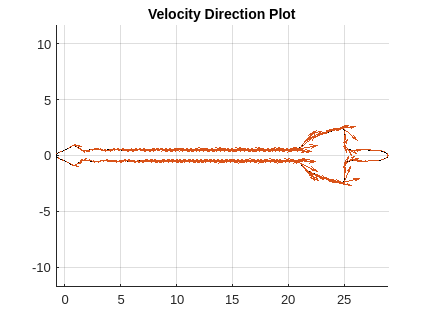




figure
hold on
grid on
axis equal
quiver_plot_skip = 4;
prof_plot(zeta(:, 1), 'k')
% quiver(real(zeta(1:quiver_plot_skip:end, 1:quiver_plot_skip:end)), imag(zeta(1:quiver_plot_skip:end, 1:quiver_plot_skip:end)), ...
%     u_zeta_radial(1:quiver_plot_skip:end, 1:quiver_plot_skip:end), v_zeta_radial(1:quiver_plot_skip:end, 1:quiver_plot_skip:end))
quiver(real(zeta(1:quiver_plot_skip:end, 1)), imag(zeta(1:quiver_plot_skip:end, 1)), u_zeta_radial(1:quiver_plot_skip:end, 1), v_zeta_radial(1:quiver_plot_skip:end, 1));
% quiver(real(zeta(1, 1:quiver_plot_skip:end)), imag(zeta(1, 1:quiver_plot_skip:end)), u_zeta_radial(1, 1:quiver_plot_skip:end), v_zeta_radial(1, 1:quiver_plot_skip:end));
title('Velocity Direction Plot')



% Compute hte pre